%Regelkarten für eine für USB-Geschwindigkeit, Toleranz
%19.6 bis 20.4
data=readtable('USB.xlsx')

data = 10×5 table
    Var1    Anna     Benni    Michael     Jan 
    ____    _____    _____    _______    _____

      1     19.71    35.99    17.387     18.45
      2     19.92    36.82     16.96     18.88
      3      19.5    37.46    17.639     18.88
      4      19.5    36.84    16.648     18.88
      5     20.34    36.62    18.541     18.87
      6      19.5    36.62    18.024     18.66
      7     19.71    37.03    18.553     18.87
      8      19.5    36.24    17.675     19.08
      9     19.51    35.77    18.169     19.08
     10      19.5    35.15    16.747     19.09


%data(:,2:6).Variables=120+1.25*randn(21,5);

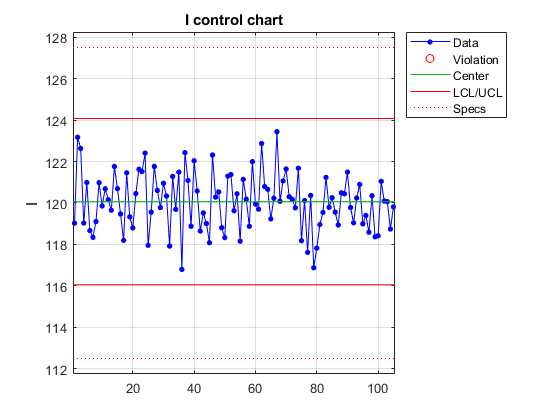

%Verschiedene Regelkarten
%igure(2)
%Einzelwertkarte
[stats_i2,plot_i2]=controlchart(data(:,2:6).Variables,data.Messzeitpunkt,"charttype","i","specs",[19.6 20.4])
grid on

cp=capability(data(:,2).Variables,[19.6 20.4])

cp = struct with fields:
       mu: 119.9734
    sigma: 1.1393
        P: 1.0000
       Pl: 2.6924e-11
       Pu: 1.9661e-11
       Cp: 2.1944
      Cpl: 2.1866
      Cpu: 2.2022
      Cpk: 2.1866


%XBAR-Chart mit s und R 
[stats_xs,plot_xs]=controlchart(data(:,2:6).Variables,data.Messzeitpunkt,'charttype',{'xbar' 's'})

stats_xs = struct with fields:
     mean: [21×1 double]
      std: [21×1 double]
        n: [21×1 double]
    range: [21×1 double]
       mu: 120.0661
    sigma: 1.3376


plot_xs = 1×2 struct array with fields:
    pts
    cl
    lcl
    ucl
    se
    n
    ooc


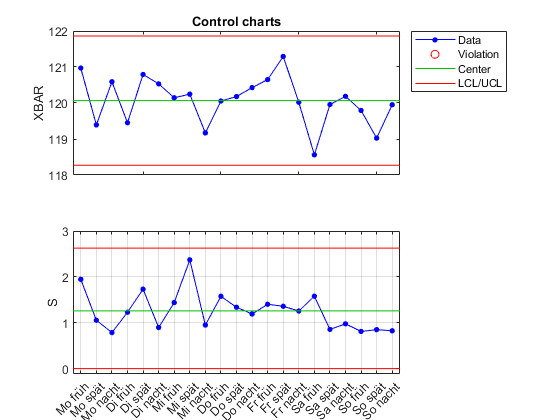

grid on
axes=gca;
axes.XTickLabelRotation=45;


[stats_xr,plot_xr]=controlchart(data(:,2:6).Variables,data.Messzeitpunkt,'charttype',{'xbar' 'r'})

stats_xr = struct with fields:
     mean: [21×1 double]
      std: [21×1 double]
        n: [21×1 double]
    range: [21×1 double]
       mu: 120.0661
    sigma: 1.3376


plot_xr = 1×2 struct array with fields:
    pts
    cl
    lcl
    ucl
    se
    n
    ooc


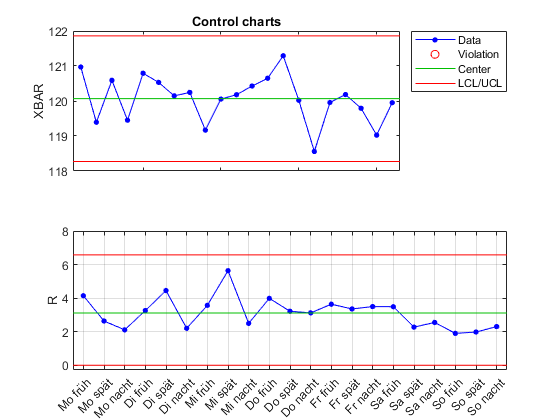

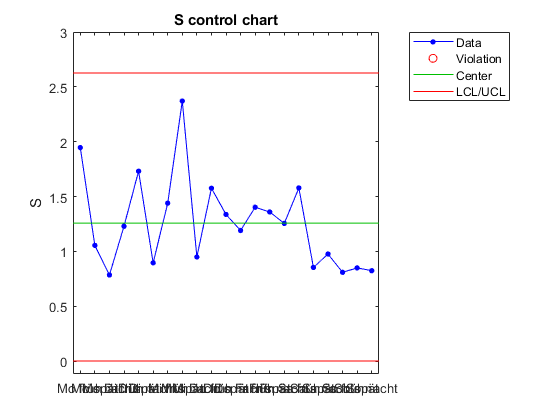

stats_s = struct with fields:
     mean: [21×1 double]
      std: [21×1 double]
        n: [21×1 double]
    range: [21×1 double]
       mu: 120.0661
    sigma: 1.3376


plot_s = struct with fields:
    pts: [21×1 double]
     cl: [21×1 double]
    lcl: [21×1 double]
    ucl: [21×1 double]
     se: [21×1 double]
      n: [21×1 double]
    ooc: [21×1 logical]


stats_test = struct with fields:
        n: [21×1 double]
     mean: [21×1 double]
        i: [21×1 double]
       mr: [21×1 double]
       mu: 1.2574
    sigma: 0.3818


plot_test = struct with fields:
    pts: [21×1 double]
     cl: [21×1 double]
    lcl: [21×1 double]
    ucl: [21×1 double]
     se: [21×1 double]
      n: [21×1 double]
    ooc: [21×1 logical]


sigma =     1.9461    1.0540    0.7844    1.2288    1.7312    0.8953    1.4395    2.3707    0.9486    1.5758    1.3363    1.1901    1.4021    1.3587    1.2547    1.5783    0.8530    0.9756    0.8087    0.8489    0.8235


variance =     3.7874    1.1109    0.6154    1.5100    2.9972    0.8015    2.0722    5.6203    0.8998    2.4831    1.7857    1.4165    1.9659    1.8461    1.5743    2.4911    0.7277    0.9517    0.6540    0.7207    0.6781


mean_daten =   120.9708  119.3919  120.5907  119.4515  120.7927  120.5321  120.1456  120.2461  119.1687  120.0549  120.1798  120.4284  120.6507  121.2923  120.0206  118.5598  119.9575  120.1846  119.7924  119.0252  119.9528


h_mean = logical
   0


p_mean = 0.7241

h_var = logical
   1


p_var = 0.0058

grid on
axes=gca;
axes.XTickLabelRotation=45;

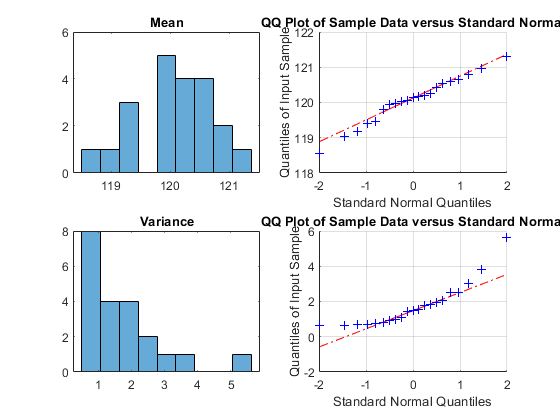

%Darstellung Histogramme und qq-Plots zu Mean und sigma bzw. Varianz, Test
%auf Normalverteilung
sigma=std(data(:,2:6).Variables')
variance=var(data(:,2:6).Variables')
mean_daten=mean(data(:,2:6).Variables')
subplot(2,2,1)
histogram(mean_daten,round(2*sqrt(21),0))
title("Mean")
subplot(2,2,2)
qqplot(mean_daten)
grid on
subplot(2,2,3)
histogram(variance,round(2*sqrt(21),0))
title("Variance")
%histogram(sqrt(variance),round(2*sqrt(21),0))
%title("sigma")
subplot(2,2,4)
qqplot(variance)
grid on

[h_mean,p_mean]=adtest(mean_daten)
[h_var,p_var]=adtest(variance)